## Gradient method for inverse kinematics

### Parameters

% Initial guess for joint angles
theta1 = pi/2;
theta2 = pi/2;
theta3 = pi/2;

% Desired end-effector position
x_desired = 2;
y_desired = 1;
phi_desired = 0;

% Gradient descent parameters
learning_rate = 1/10;       % Learning rate
max_iterations = 1000;      % Maximum number of iterations
tolerance = 1e-6;           % Tolerance for convergence

### Plotting setup

% Plotting setup for x-coordinate
fig_x = figure('WindowStyle', 'normal');
xlabel('Iteration');
ylabel('X');
title('End-Effector X Movement');
hold on;

% Plotting setup for y-coordinate
fig_y = figure('WindowStyle', 'normal');
xlabel('Iteration');
ylabel('Y');
title('End-Effector Y Movement');
hold on;

% Plotting setup for y-coordinate
fig_phi = figure('WindowStyle', 'normal');
xlabel('Iteration');
ylabel('PHI');
title('End-Effector PHI Movement');
hold on;

% Initialize error vector
errors = zeros(1, max_iterations);

### Gradient method algorithm

% Initial end-effector position
[x, y, phi] = forward_kinematics(theta1, theta2, theta3);
figure(fig_x);
plot(0, x, 'bo', 'MarkerSize', 10, 'DisplayName', 'Initial X');
figure(fig_y);
plot(0, y, 'bo', 'MarkerSize', 10, 'DisplayName', 'Initial Y');
figure(fig_phi);
plot(0, phi, 'bo', 'MarkerSize', 10, 'DisplayName', 'Initial PHI');


% Gradient descent optimization
for iter = 1:max_iterations
    % Calculate the error
    [x, y, phi] = forward_kinematics(theta1, theta2, theta3);
    error = error_function(x_desired, y_desired, phi_desired, theta1, theta2, theta3);
    errors(iter) = error;

    % Display current iteration and error
    fprintf('Iteration %d \n', iter);
    fprintf('\tIK: [theta1: %.4f, theta2: %.4f, theta3: %.4f]\n', theta1, theta2, theta3);
    fprintf('\tDK: [x: %.4f, y: %.4f, phi: %.4f]\n', x, y, phi);
    fprintf('\tError: %.8f\n', error);
    
    % Check for convergence
    if error < tolerance
        disp('Converged!');
        break;
    end


    % Plot the movement of the end-effector for x-coordinate
    figure(fig_x);
    plot(iter, x, 'ko-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', ['Iteration ', num2str(iter)]);
    % Plot the movement of the end-effector for y-coordinate
    figure(fig_y);
    plot(iter, y, 'ko-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', ['Iteration ', num2str(iter)]);
    % Plot the movement of the end-effector for phi-coordinate
    figure(fig_phi);
    plot(iter, phi, 'ko-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', ['Iteration ', num2str(iter)]);


    % Calculate the Jacobian matrix
    J = jacobian(theta1, theta2, theta3);
    
    % Calculate the gradient of the error
    grad_error = J' * [(x_desired - x); (y_desired - y); (phi_desired - phi)];
    
    % Update the joint angles using gradient descent
    theta1 = theta1 + learning_rate * grad_error(1);
    theta2 = theta2 + learning_rate * grad_error(2);
    theta3 = theta3 + learning_rate * grad_error(3);
end

Iteration 1 


	IK: [theta1: 1.5708, theta2: 1.5708, theta3: 1.5708]


	DK: [x: -1.0000, y: 0.0000, phi: 4.7124]


	Error: 5.67508677


Iteration 2 


	IK: [theta1: 0.9996, theta2: 1.2996, theta3: 1.3996]


	DK: [x: -0.9737, y: 1.0588, phi: 3.6987]


	Error: 4.74623938


Iteration 3 


	IK: [theta1: 0.3206, theta2: 0.8739, theta3: 1.1919]


	DK: [x: 0.5885, y: 1.9306, phi: 2.3864]


	Error: 2.92455371


Iteration 4 


	IK: [theta1: -0.2453, theta2: 0.4408, theta3: 0.9243]


	DK: [x: 2.3870, y: 0.8513, phi: 1.1197]


	Error: 1.19398791


Iteration 5 


	IK: [theta1: -0.2889, theta2: 0.3922, theta3: 0.8536]


	DK: [x: 2.5292, y: 0.6357, phi: 0.9570]


	Error: 1.15262915


Iteration 6 


	IK: [theta1: -0.2588, theta2: 0.4025, theta3: 0.8222]


	DK: [x: 2.5251, y: 0.7098, phi: 0.9658]


	Error: 1.13702079


Iteration 7 


	IK: [theta1: -0.2448, theta2: 0.4018, theta3: 0.7853]


	DK: [x: 2.5458, y: 0.7229, phi: 0.9423]


	Error: 1.12366113


Iteration 8 


	IK: [theta1: -0.2290, theta2: 0.4039, theta3: 0.7515]


	DK: [x: 2.5593, y: 0.7464, phi: 0.9264]


	Error: 1.11147514


Iteration 9 


	IK: [theta1: -0.2150, theta2: 0.4060, theta3: 0.7188]


	DK: [x: 2.5728, y: 0.7657, phi: 0.9097]


	Error: 1.10024670


Iteration 10 


	IK: [theta1: -0.2019, theta2: 0.4085, theta3: 0.6874]


	DK: [x: 2.5847, y: 0.7842, phi: 0.8940]


	Error: 1.08982581


Iteration 11 


	IK: [theta1: -0.1896, theta2: 0.4113, theta3: 0.6571]


	DK: [x: 2.5957, y: 0.8013, phi: 0.8788]


	Error: 1.08008947


Iteration 12 


	IK: [theta1: -0.1782, theta2: 0.4144, theta3: 0.6278]


	DK: [x: 2.6058, y: 0.8173, phi: 0.8640]


	Error: 1.07093490


Iteration 13 


	IK: [theta1: -0.1675, theta2: 0.4179, theta3: 0.5993]


	DK: [x: 2.6150, y: 0.8323, phi: 0.8498]


	Error: 1.06227557


Iteration 14 


	IK: [theta1: -0.1574, theta2: 0.4217, theta3: 0.5716]


	DK: [x: 2.6234, y: 0.8464, phi: 0.8359]


	Error: 1.05403805


Iteration 15 


	IK: [theta1: -0.1479, theta2: 0.4258, theta3: 0.5446]


	DK: [x: 2.6312, y: 0.8597, phi: 0.8224]


	Error: 1.04615960


Iteration 16 


	IK: [theta1: -0.1390, theta2: 0.4301, theta3: 0.5181]


	DK: [x: 2.6383, y: 0.8723, phi: 0.8093]


	Error: 1.03858622


Iteration 17 


	IK: [theta1: -0.1305, theta2: 0.4348, theta3: 0.4922]


	DK: [x: 2.6448, y: 0.8842, phi: 0.7964]


	Error: 1.03127110


Iteration 18 


	IK: [theta1: -0.1226, theta2: 0.4397, theta3: 0.4668]


	DK: [x: 2.6508, y: 0.8956, phi: 0.7839]


	Error: 1.02417338


Iteration 19 


	IK: [theta1: -0.1150, theta2: 0.4448, theta3: 0.4417]


	DK: [x: 2.6563, y: 0.9064, phi: 0.7716]


	Error: 1.01725715


Iteration 20 


	IK: [theta1: -0.1078, theta2: 0.4503, theta3: 0.4170]


	DK: [x: 2.6613, y: 0.9168, phi: 0.7595]


	Error: 1.01049062


Iteration 21 


	IK: [theta1: -0.1010, theta2: 0.4559, theta3: 0.3927]


	DK: [x: 2.6659, y: 0.9266, phi: 0.7476]


	Error: 1.00384546


Iteration 22 


	IK: [theta1: -0.0945, theta2: 0.4618, theta3: 0.3685]


	DK: [x: 2.6700, y: 0.9361, phi: 0.7359]


	Error: 0.99729628


Iteration 23 


	IK: [theta1: -0.0883, theta2: 0.4680, theta3: 0.3447]


	DK: [x: 2.6738, y: 0.9452, phi: 0.7244]


	Error: 0.99082011


Iteration 24 


	IK: [theta1: -0.0824, theta2: 0.4744, theta3: 0.3210]


	DK: [x: 2.6772, y: 0.9539, phi: 0.7130]


	Error: 0.98439609


Iteration 25 


	IK: [theta1: -0.0767, theta2: 0.4810, theta3: 0.2975]


	DK: [x: 2.6802, y: 0.9622, phi: 0.7017]


	Error: 0.97800513


Iteration 26 


	IK: [theta1: -0.0713, theta2: 0.4878, theta3: 0.2741]


	DK: [x: 2.6828, y: 0.9703, phi: 0.6906]


	Error: 0.97162965


Iteration 27 


	IK: [theta1: -0.0662, theta2: 0.4949, theta3: 0.2508]


	DK: [x: 2.6852, y: 0.9781, phi: 0.6796]


	Error: 0.96525339


Iteration 28 


	IK: [theta1: -0.0612, theta2: 0.5022, theta3: 0.2276]


	DK: [x: 2.6871, y: 0.9855, phi: 0.6686]


	Error: 0.95886120


Iteration 29 


	IK: [theta1: -0.0565, theta2: 0.5097, theta3: 0.2045]


	DK: [x: 2.6888, y: 0.9928, phi: 0.6577]


	Error: 0.95243887


Iteration 30 


	IK: [theta1: -0.0519, theta2: 0.5174, theta3: 0.1814]


	DK: [x: 2.6902, y: 0.9997, phi: 0.6469]


	Error: 0.94597306


Iteration 31 


	IK: [theta1: -0.0475, theta2: 0.5254, theta3: 0.1583]


	DK: [x: 2.6912, y: 1.0065, phi: 0.6362]


	Error: 0.93945118


Iteration 32 


	IK: [theta1: -0.0433, theta2: 0.5335, theta3: 0.1353]


	DK: [x: 2.6920, y: 1.0130, phi: 0.6255]


	Error: 0.93286124


Iteration 33 


	IK: [theta1: -0.0393, theta2: 0.5419, theta3: 0.1122]


	DK: [x: 2.6925, y: 1.0193, phi: 0.6148]


	Error: 0.92619187


Iteration 34 


	IK: [theta1: -0.0353, theta2: 0.5504, theta3: 0.0891]


	DK: [x: 2.6926, y: 1.0253, phi: 0.6042]


	Error: 0.91943220


Iteration 35 


	IK: [theta1: -0.0316, theta2: 0.5592, theta3: 0.0659]


	DK: [x: 2.6925, y: 1.0312, phi: 0.5935]


	Error: 0.91257185


Iteration 36 


	IK: [theta1: -0.0279, theta2: 0.5681, theta3: 0.0427]


	DK: [x: 2.6921, y: 1.0369, phi: 0.5829]


	Error: 0.90560086


Iteration 37 


	IK: [theta1: -0.0244, theta2: 0.5773, theta3: 0.0194]


	DK: [x: 2.6913, y: 1.0424, phi: 0.5723]


	Error: 0.89850969


Iteration 38 


	IK: [theta1: -0.0210, theta2: 0.5866, theta3: -0.0039]


	DK: [x: 2.6903, y: 1.0477, phi: 0.5617]


	Error: 0.89128923


Iteration 39 


	IK: [theta1: -0.0176, theta2: 0.5962, theta3: -0.0274]


	DK: [x: 2.6890, y: 1.0528, phi: 0.5512]


	Error: 0.88393070


Iteration 40 


	IK: [theta1: -0.0144, theta2: 0.6059, theta3: -0.0509]


	DK: [x: 2.6874, y: 1.0578, phi: 0.5406]


	Error: 0.87642577


Iteration 41 


	IK: [theta1: -0.0113, theta2: 0.6158, theta3: -0.0745]


	DK: [x: 2.6856, y: 1.0626, phi: 0.5300]


	Error: 0.86876647


Iteration 42 


	IK: [theta1: -0.0082, theta2: 0.6259, theta3: -0.0983]


	DK: [x: 2.6834, y: 1.0672, phi: 0.5193]


	Error: 0.86094525


Iteration 43 


	IK: [theta1: -0.0053, theta2: 0.6361, theta3: -0.1221]


	DK: [x: 2.6809, y: 1.0716, phi: 0.5087]


	Error: 0.85295497


Iteration 44 


	IK: [theta1: -0.0024, theta2: 0.6465, theta3: -0.1461]


	DK: [x: 2.6781, y: 1.0759, phi: 0.4981]


	Error: 0.84478896


Iteration 45 


	IK: [theta1: 0.0005, theta2: 0.6571, theta3: -0.1702]


	DK: [x: 2.6750, y: 1.0800, phi: 0.4874]


	Error: 0.83644101


Iteration 46 


	IK: [theta1: 0.0032, theta2: 0.6678, theta3: -0.1944]


	DK: [x: 2.6717, y: 1.0839, phi: 0.4767]


	Error: 0.82790545


Iteration 47 


	IK: [theta1: 0.0059, theta2: 0.6787, theta3: -0.2187]


	DK: [x: 2.6680, y: 1.0877, phi: 0.4660]


	Error: 0.81917711


Iteration 48 


	IK: [theta1: 0.0086, theta2: 0.6898, theta3: -0.2431]


	DK: [x: 2.6640, y: 1.0913, phi: 0.4553]


	Error: 0.81025146


Iteration 49 


	IK: [theta1: 0.0112, theta2: 0.7009, theta3: -0.2676]


	DK: [x: 2.6597, y: 1.0947, phi: 0.4445]


	Error: 0.80112457


Iteration 50 


	IK: [theta1: 0.0138, theta2: 0.7122, theta3: -0.2922]


	DK: [x: 2.6551, y: 1.0980, phi: 0.4338]


	Error: 0.79179321


Iteration 51 


	IK: [theta1: 0.0163, theta2: 0.7237, theta3: -0.3170]


	DK: [x: 2.6502, y: 1.1011, phi: 0.4230]


	Error: 0.78225487


Iteration 52 


	IK: [theta1: 0.0188, theta2: 0.7352, theta3: -0.3418]


	DK: [x: 2.6450, y: 1.1041, phi: 0.4122]


	Error: 0.77250782


Iteration 53 


	IK: [theta1: 0.0213, theta2: 0.7469, theta3: -0.3667]


	DK: [x: 2.6395, y: 1.1068, phi: 0.4014]


	Error: 0.76255116


Iteration 54 


	IK: [theta1: 0.0237, theta2: 0.7586, theta3: -0.3917]


	DK: [x: 2.6336, y: 1.1094, phi: 0.3906]


	Error: 0.75238487


Iteration 55 


	IK: [theta1: 0.0261, theta2: 0.7705, theta3: -0.4168]


	DK: [x: 2.6275, y: 1.1119, phi: 0.3798]


	Error: 0.74200985


Iteration 56 


	IK: [theta1: 0.0285, theta2: 0.7824, theta3: -0.4419]


	DK: [x: 2.6211, y: 1.1142, phi: 0.3691]


	Error: 0.73142798


Iteration 57 


	IK: [theta1: 0.0309, theta2: 0.7944, theta3: -0.4670]


	DK: [x: 2.6144, y: 1.1163, phi: 0.3583]


	Error: 0.72064215


Iteration 58 


	IK: [theta1: 0.0332, theta2: 0.8065, theta3: -0.4922]


	DK: [x: 2.6073, y: 1.1183, phi: 0.3475]


	Error: 0.70965628


Iteration 59 


	IK: [theta1: 0.0356, theta2: 0.8186, theta3: -0.5174]


	DK: [x: 2.6000, y: 1.1201, phi: 0.3368]


	Error: 0.69847540


Iteration 60 


	IK: [theta1: 0.0379, theta2: 0.8308, theta3: -0.5426]


	DK: [x: 2.5924, y: 1.1217, phi: 0.3261]


	Error: 0.68710560


Iteration 61 


	IK: [theta1: 0.0402, theta2: 0.8430, theta3: -0.5677]


	DK: [x: 2.5846, y: 1.1232, phi: 0.3154]


	Error: 0.67555414


Iteration 62 


	IK: [theta1: 0.0425, theta2: 0.8552, theta3: -0.5929]


	DK: [x: 2.5764, y: 1.1245, phi: 0.3048]


	Error: 0.66382934


Iteration 63 


	IK: [theta1: 0.0447, theta2: 0.8675, theta3: -0.6179]


	DK: [x: 2.5680, y: 1.1256, phi: 0.2943]


	Error: 0.65194069


Iteration 64 


	IK: [theta1: 0.0470, theta2: 0.8797, theta3: -0.6429]


	DK: [x: 2.5594, y: 1.1266, phi: 0.2838]


	Error: 0.63989874


Iteration 65 


	IK: [theta1: 0.0492, theta2: 0.8920, theta3: -0.6678]


	DK: [x: 2.5505, y: 1.1275, phi: 0.2734]


	Error: 0.62771513


Iteration 66 


	IK: [theta1: 0.0514, theta2: 0.9042, theta3: -0.6925]


	DK: [x: 2.5414, y: 1.1282, phi: 0.2631]


	Error: 0.61540253


Iteration 67 


	IK: [theta1: 0.0536, theta2: 0.9164, theta3: -0.7171]


	DK: [x: 2.5320, y: 1.1287, phi: 0.2529]


	Error: 0.60297460


Iteration 68 


	IK: [theta1: 0.0558, theta2: 0.9286, theta3: -0.7416]


	DK: [x: 2.5225, y: 1.1291, phi: 0.2428]


	Error: 0.59044589


Iteration 69 


	IK: [theta1: 0.0579, theta2: 0.9407, theta3: -0.7658]


	DK: [x: 2.5128, y: 1.1294, phi: 0.2328]


	Error: 0.57783183


Iteration 70 


	IK: [theta1: 0.0600, theta2: 0.9528, theta3: -0.7898]


	DK: [x: 2.5029, y: 1.1295, phi: 0.2230]


	Error: 0.56514857


Iteration 71 


	IK: [theta1: 0.0621, theta2: 0.9648, theta3: -0.8137]


	DK: [x: 2.4929, y: 1.1295, phi: 0.2133]


	Error: 0.55241292


Iteration 72 


	IK: [theta1: 0.0642, theta2: 0.9767, theta3: -0.8372]


	DK: [x: 2.4827, y: 1.1293, phi: 0.2037]


	Error: 0.53964225


Iteration 73 


	IK: [theta1: 0.0662, theta2: 0.9886, theta3: -0.8605]


	DK: [x: 2.4724, y: 1.1291, phi: 0.1943]


	Error: 0.52685437


Iteration 74 


	IK: [theta1: 0.0682, theta2: 1.0003, theta3: -0.8834]


	DK: [x: 2.4620, y: 1.1287, phi: 0.1851]


	Error: 0.51406737


Iteration 75 


	IK: [theta1: 0.0702, theta2: 1.0120, theta3: -0.9061]


	DK: [x: 2.4515, y: 1.1282, phi: 0.1760]


	Error: 0.50129954


Iteration 76 


	IK: [theta1: 0.0721, theta2: 1.0235, theta3: -0.9284]


	DK: [x: 2.4410, y: 1.1276, phi: 0.1672]


	Error: 0.48856924


Iteration 77 


	IK: [theta1: 0.0739, theta2: 1.0349, theta3: -0.9504]


	DK: [x: 2.4304, y: 1.1269, phi: 0.1585]


	Error: 0.47589474


Iteration 78 


	IK: [theta1: 0.0758, theta2: 1.0462, theta3: -0.9720]


	DK: [x: 2.4198, y: 1.1261, phi: 0.1500]


	Error: 0.46329411


Iteration 79 


	IK: [theta1: 0.0775, theta2: 1.0574, theta3: -0.9932]


	DK: [x: 2.4092, y: 1.1252, phi: 0.1417]


	Error: 0.45078507


Iteration 80 


	IK: [theta1: 0.0792, theta2: 1.0684, theta3: -1.0139]


	DK: [x: 2.3986, y: 1.1242, phi: 0.1337]


	Error: 0.43838492


Iteration 81 


	IK: [theta1: 0.0809, theta2: 1.0793, theta3: -1.0343]


	DK: [x: 2.3880, y: 1.1232, phi: 0.1258]


	Error: 0.42611037


Iteration 82 


	IK: [theta1: 0.0825, theta2: 1.0900, theta3: -1.0542]


	DK: [x: 2.3775, y: 1.1220, phi: 0.1182]


	Error: 0.41397746


Iteration 83 


	IK: [theta1: 0.0840, theta2: 1.1006, theta3: -1.0737]


	DK: [x: 2.3670, y: 1.1208, phi: 0.1108]


	Error: 0.40200146


Iteration 84 


	IK: [theta1: 0.0855, theta2: 1.1110, theta3: -1.0928]


	DK: [x: 2.3567, y: 1.1196, phi: 0.1037]


	Error: 0.39019679


Iteration 85 


	IK: [theta1: 0.0868, theta2: 1.1212, theta3: -1.1113]


	DK: [x: 2.3464, y: 1.1183, phi: 0.0967]


	Error: 0.37857692


Iteration 86 


	IK: [theta1: 0.0882, theta2: 1.1313, theta3: -1.1294]


	DK: [x: 2.3362, y: 1.1169, phi: 0.0900]


	Error: 0.36715434


Iteration 87 


	IK: [theta1: 0.0894, theta2: 1.1412, theta3: -1.1471]


	DK: [x: 2.3262, y: 1.1155, phi: 0.0836]


	Error: 0.35594048


Iteration 88 


	IK: [theta1: 0.0906, theta2: 1.1510, theta3: -1.1642]


	DK: [x: 2.3162, y: 1.1140, phi: 0.0774]


	Error: 0.34494571


Iteration 89 


	IK: [theta1: 0.0916, theta2: 1.1606, theta3: -1.1809]


	DK: [x: 2.3065, y: 1.1125, phi: 0.0714]


	Error: 0.33417926


Iteration 90 


	IK: [theta1: 0.0927, theta2: 1.1700, theta3: -1.1970]


	DK: [x: 2.2969, y: 1.1110, phi: 0.0656]


	Error: 0.32364926


Iteration 91 


	IK: [theta1: 0.0936, theta2: 1.1792, theta3: -1.2127]


	DK: [x: 2.2874, y: 1.1094, phi: 0.0601]


	Error: 0.31336271


Iteration 92 


	IK: [theta1: 0.0944, theta2: 1.1883, theta3: -1.2279]


	DK: [x: 2.2782, y: 1.1078, phi: 0.0548]


	Error: 0.30332550


Iteration 93 


	IK: [theta1: 0.0952, theta2: 1.1972, theta3: -1.2426]


	DK: [x: 2.2691, y: 1.1062, phi: 0.0497]


	Error: 0.29354242


Iteration 94 


	IK: [theta1: 0.0959, theta2: 1.2059, theta3: -1.2569]


	DK: [x: 2.2602, y: 1.1046, phi: 0.0449]


	Error: 0.28401720


Iteration 95 


	IK: [theta1: 0.0965, theta2: 1.2144, theta3: -1.2707]


	DK: [x: 2.2515, y: 1.1030, phi: 0.0402]


	Error: 0.27475254


Iteration 96 


	IK: [theta1: 0.0970, theta2: 1.2228, theta3: -1.2840]


	DK: [x: 2.2430, y: 1.1014, phi: 0.0358]


	Error: 0.26575014


Iteration 97 


	IK: [theta1: 0.0975, theta2: 1.2309, theta3: -1.2968]


	DK: [x: 2.2348, y: 1.0997, phi: 0.0316]


	Error: 0.25701078


Iteration 98 


	IK: [theta1: 0.0979, theta2: 1.2390, theta3: -1.3092]


	DK: [x: 2.2267, y: 1.0981, phi: 0.0276]


	Error: 0.24853434


Iteration 99 


	IK: [theta1: 0.0981, theta2: 1.2468, theta3: -1.3211]


	DK: [x: 2.2188, y: 1.0964, phi: 0.0238]


	Error: 0.24031989


Iteration 100 


	IK: [theta1: 0.0984, theta2: 1.2545, theta3: -1.3326]


	DK: [x: 2.2112, y: 1.0948, phi: 0.0202]


	Error: 0.23236571


Iteration 101 


	IK: [theta1: 0.0985, theta2: 1.2620, theta3: -1.3437]


	DK: [x: 2.2038, y: 1.0931, phi: 0.0168]


	Error: 0.22466938


Iteration 102 


	IK: [theta1: 0.0986, theta2: 1.2693, theta3: -1.3543]


	DK: [x: 2.1966, y: 1.0915, phi: 0.0136]


	Error: 0.21722786


Iteration 103 


	IK: [theta1: 0.0986, theta2: 1.2765, theta3: -1.3646]


	DK: [x: 2.1896, y: 1.0898, phi: 0.0105]


	Error: 0.21003749


Iteration 104 


	IK: [theta1: 0.0985, theta2: 1.2835, theta3: -1.3744]


	DK: [x: 2.1828, y: 1.0882, phi: 0.0076]


	Error: 0.20309411


Iteration 105 


	IK: [theta1: 0.0984, theta2: 1.2903, theta3: -1.3839]


	DK: [x: 2.1762, y: 1.0866, phi: 0.0049]


	Error: 0.19639309


Iteration 106 


	IK: [theta1: 0.0982, theta2: 1.2970, theta3: -1.3929]


	DK: [x: 2.1698, y: 1.0850, phi: 0.0023]


	Error: 0.18992940


Iteration 107 


	IK: [theta1: 0.0980, theta2: 1.3036, theta3: -1.4016]


	DK: [x: 2.1637, y: 1.0834, phi: -0.0001]


	Error: 0.18369767


Iteration 108 


	IK: [theta1: 0.0976, theta2: 1.3100, theta3: -1.4100]


	DK: [x: 2.1577, y: 1.0819, phi: -0.0023]


	Error: 0.17769223


Iteration 109 


	IK: [theta1: 0.0973, theta2: 1.3162, theta3: -1.4179]


	DK: [x: 2.1519, y: 1.0803, phi: -0.0045]


	Error: 0.17190716


Iteration 110 


	IK: [theta1: 0.0968, theta2: 1.3223, theta3: -1.4256]


	DK: [x: 2.1464, y: 1.0788, phi: -0.0064]


	Error: 0.16633635


Iteration 111 


	IK: [theta1: 0.0964, theta2: 1.3283, theta3: -1.4329]


	DK: [x: 2.1410, y: 1.0773, phi: -0.0083]


	Error: 0.16097355


Iteration 112 


	IK: [theta1: 0.0958, theta2: 1.3341, theta3: -1.4399]


	DK: [x: 2.1358, y: 1.0758, phi: -0.0100]


	Error: 0.15581240


Iteration 113 


	IK: [theta1: 0.0953, theta2: 1.3397, theta3: -1.4466]


	DK: [x: 2.1308, y: 1.0743, phi: -0.0116]


	Error: 0.15084645


Iteration 114 


	IK: [theta1: 0.0947, theta2: 1.3453, theta3: -1.4531]


	DK: [x: 2.1259, y: 1.0728, phi: -0.0131]


	Error: 0.14606924


Iteration 115 


	IK: [theta1: 0.0940, theta2: 1.3507, theta3: -1.4592]


	DK: [x: 2.1213, y: 1.0714, phi: -0.0145]


	Error: 0.14147428


Iteration 116 


	IK: [theta1: 0.0933, theta2: 1.3559, theta3: -1.4651]


	DK: [x: 2.1168, y: 1.0700, phi: -0.0158]


	Error: 0.13705514


Iteration 117 


	IK: [theta1: 0.0926, theta2: 1.3611, theta3: -1.4707]


	DK: [x: 2.1125, y: 1.0686, phi: -0.0170]


	Error: 0.13280541


Iteration 118 


	IK: [theta1: 0.0918, theta2: 1.3661, theta3: -1.4760]


	DK: [x: 2.1083, y: 1.0672, phi: -0.0181]


	Error: 0.12871876


Iteration 119 


	IK: [theta1: 0.0910, theta2: 1.3710, theta3: -1.4811]


	DK: [x: 2.1043, y: 1.0658, phi: -0.0191]


	Error: 0.12478897


Iteration 120 


	IK: [theta1: 0.0902, theta2: 1.3758, theta3: -1.4860]


	DK: [x: 2.1004, y: 1.0645, phi: -0.0200]


	Error: 0.12100991


Iteration 121 


	IK: [theta1: 0.0893, theta2: 1.3804, theta3: -1.4906]


	DK: [x: 2.0967, y: 1.0632, phi: -0.0209]


	Error: 0.11737560


Iteration 122 


	IK: [theta1: 0.0884, theta2: 1.3850, theta3: -1.4951]


	DK: [x: 2.0931, y: 1.0619, phi: -0.0217]


	Error: 0.11388017


Iteration 123 


	IK: [theta1: 0.0875, theta2: 1.3894, theta3: -1.4993]


	DK: [x: 2.0896, y: 1.0606, phi: -0.0224]


	Error: 0.11051793


Iteration 124 


	IK: [theta1: 0.0866, theta2: 1.3938, theta3: -1.5033]


	DK: [x: 2.0863, y: 1.0594, phi: -0.0230]


	Error: 0.10728332


Iteration 125 


	IK: [theta1: 0.0856, theta2: 1.3980, theta3: -1.5072]


	DK: [x: 2.0831, y: 1.0582, phi: -0.0235]


	Error: 0.10417096


Iteration 126 


	IK: [theta1: 0.0847, theta2: 1.4021, theta3: -1.5108]


	DK: [x: 2.0801, y: 1.0570, phi: -0.0241]


	Error: 0.10117565


Iteration 127 


	IK: [theta1: 0.0837, theta2: 1.4061, theta3: -1.5143]


	DK: [x: 2.0771, y: 1.0558, phi: -0.0245]


	Error: 0.09829236


Iteration 128 


	IK: [theta1: 0.0827, theta2: 1.4100, theta3: -1.5176]


	DK: [x: 2.0743, y: 1.0546, phi: -0.0249]


	Error: 0.09551621


Iteration 129 


	IK: [theta1: 0.0817, theta2: 1.4138, theta3: -1.5208]


	DK: [x: 2.0716, y: 1.0535, phi: -0.0252]


	Error: 0.09284253


Iteration 130 


	IK: [theta1: 0.0807, theta2: 1.4176, theta3: -1.5238]


	DK: [x: 2.0689, y: 1.0524, phi: -0.0255]


	Error: 0.09026682


Iteration 131 


	IK: [theta1: 0.0796, theta2: 1.4212, theta3: -1.5266]


	DK: [x: 2.0664, y: 1.0513, phi: -0.0258]


	Error: 0.08778475


Iteration 132 


	IK: [theta1: 0.0786, theta2: 1.4248, theta3: -1.5294]


	DK: [x: 2.0640, y: 1.0502, phi: -0.0260]


	Error: 0.08539218


Iteration 133 


	IK: [theta1: 0.0775, theta2: 1.4282, theta3: -1.5319]


	DK: [x: 2.0616, y: 1.0492, phi: -0.0262]


	Error: 0.08308512


Iteration 134 


	IK: [theta1: 0.0765, theta2: 1.4316, theta3: -1.5344]


	DK: [x: 2.0594, y: 1.0481, phi: -0.0263]


	Error: 0.08085977


Iteration 135 


	IK: [theta1: 0.0754, theta2: 1.4349, theta3: -1.5367]


	DK: [x: 2.0573, y: 1.0471, phi: -0.0264]


	Error: 0.07871249


Iteration 136 


	IK: [theta1: 0.0744, theta2: 1.4381, theta3: -1.5390]


	DK: [x: 2.0552, y: 1.0461, phi: -0.0265]


	Error: 0.07663980


Iteration 137 


	IK: [theta1: 0.0733, theta2: 1.4412, theta3: -1.5411]


	DK: [x: 2.0532, y: 1.0452, phi: -0.0265]


	Error: 0.07463838


Iteration 138 


	IK: [theta1: 0.0723, theta2: 1.4443, theta3: -1.5431]


	DK: [x: 2.0513, y: 1.0442, phi: -0.0265]


	Error: 0.07270508


Iteration 139 


	IK: [theta1: 0.0712, theta2: 1.4473, theta3: -1.5450]


	DK: [x: 2.0494, y: 1.0433, phi: -0.0265]


	Error: 0.07083686


Iteration 140 


	IK: [theta1: 0.0701, theta2: 1.4502, theta3: -1.5468]


	DK: [x: 2.0477, y: 1.0423, phi: -0.0265]


	Error: 0.06903086


Iteration 141 


	IK: [theta1: 0.0691, theta2: 1.4530, theta3: -1.5485]


	DK: [x: 2.0460, y: 1.0414, phi: -0.0264]


	Error: 0.06728434


Iteration 142 


	IK: [theta1: 0.0680, theta2: 1.4558, theta3: -1.5501]


	DK: [x: 2.0443, y: 1.0406, phi: -0.0263]


	Error: 0.06559470


Iteration 143 


	IK: [theta1: 0.0670, theta2: 1.4585, theta3: -1.5516]


	DK: [x: 2.0428, y: 1.0397, phi: -0.0262]


	Error: 0.06395947


Iteration 144 


	IK: [theta1: 0.0659, theta2: 1.4611, theta3: -1.5531]


	DK: [x: 2.0412, y: 1.0389, phi: -0.0261]


	Error: 0.06237630


Iteration 145 


	IK: [theta1: 0.0649, theta2: 1.4637, theta3: -1.5545]


	DK: [x: 2.0398, y: 1.0380, phi: -0.0259]


	Error: 0.06084294


Iteration 146 


	IK: [theta1: 0.0639, theta2: 1.4662, theta3: -1.5558]


	DK: [x: 2.0384, y: 1.0372, phi: -0.0258]


	Error: 0.05935728


Iteration 147 


	IK: [theta1: 0.0628, theta2: 1.4686, theta3: -1.5570]


	DK: [x: 2.0370, y: 1.0364, phi: -0.0256]


	Error: 0.05791731


Iteration 148 


	IK: [theta1: 0.0618, theta2: 1.4710, theta3: -1.5582]


	DK: [x: 2.0358, y: 1.0356, phi: -0.0254]


	Error: 0.05652110


Iteration 149 


	IK: [theta1: 0.0608, theta2: 1.4733, theta3: -1.5593]


	DK: [x: 2.0345, y: 1.0349, phi: -0.0252]


	Error: 0.05516684


Iteration 150 


	IK: [theta1: 0.0598, theta2: 1.4756, theta3: -1.5604]


	DK: [x: 2.0333, y: 1.0341, phi: -0.0250]


	Error: 0.05385281


Iteration 151 


	IK: [theta1: 0.0588, theta2: 1.4778, theta3: -1.5614]


	DK: [x: 2.0322, y: 1.0334, phi: -0.0248]


	Error: 0.05257737


Iteration 152 


	IK: [theta1: 0.0578, theta2: 1.4799, theta3: -1.5623]


	DK: [x: 2.0311, y: 1.0327, phi: -0.0246]


	Error: 0.05133897


Iteration 153 


	IK: [theta1: 0.0568, theta2: 1.4821, theta3: -1.5632]


	DK: [x: 2.0300, y: 1.0320, phi: -0.0243]


	Error: 0.05013613


Iteration 154 


	IK: [theta1: 0.0559, theta2: 1.4841, theta3: -1.5640]


	DK: [x: 2.0290, y: 1.0313, phi: -0.0241]


	Error: 0.04896746


Iteration 155 


	IK: [theta1: 0.0549, theta2: 1.4861, theta3: -1.5648]


	DK: [x: 2.0280, y: 1.0306, phi: -0.0238]


	Error: 0.04783162


Iteration 156 


	IK: [theta1: 0.0540, theta2: 1.4881, theta3: -1.5656]


	DK: [x: 2.0270, y: 1.0300, phi: -0.0236]


	Error: 0.04672735


Iteration 157 


	IK: [theta1: 0.0530, theta2: 1.4900, theta3: -1.5663]


	DK: [x: 2.0261, y: 1.0293, phi: -0.0233]


	Error: 0.04565346


Iteration 158 


	IK: [theta1: 0.0521, theta2: 1.4918, theta3: -1.5670]


	DK: [x: 2.0252, y: 1.0287, phi: -0.0230]


	Error: 0.04460880


Iteration 159 


	IK: [theta1: 0.0512, theta2: 1.4937, theta3: -1.5676]


	DK: [x: 2.0244, y: 1.0281, phi: -0.0227]


	Error: 0.04359230


Iteration 160 


	IK: [theta1: 0.0503, theta2: 1.4954, theta3: -1.5682]


	DK: [x: 2.0236, y: 1.0275, phi: -0.0225]


	Error: 0.04260292


Iteration 161 


	IK: [theta1: 0.0494, theta2: 1.4972, theta3: -1.5687]


	DK: [x: 2.0228, y: 1.0269, phi: -0.0222]


	Error: 0.04163970


Iteration 162 


	IK: [theta1: 0.0485, theta2: 1.4989, theta3: -1.5693]


	DK: [x: 2.0220, y: 1.0263, phi: -0.0219]


	Error: 0.04070170


Iteration 163 


	IK: [theta1: 0.0476, theta2: 1.5005, theta3: -1.5697]


	DK: [x: 2.0213, y: 1.0258, phi: -0.0216]


	Error: 0.03978803


Iteration 164 


	IK: [theta1: 0.0468, theta2: 1.5021, theta3: -1.5702]


	DK: [x: 2.0206, y: 1.0252, phi: -0.0213]


	Error: 0.03889786


Iteration 165 


	IK: [theta1: 0.0459, theta2: 1.5037, theta3: -1.5706]


	DK: [x: 2.0199, y: 1.0247, phi: -0.0210]


	Error: 0.03803037


Iteration 166 


	IK: [theta1: 0.0451, theta2: 1.5052, theta3: -1.5710]


	DK: [x: 2.0193, y: 1.0241, phi: -0.0207]


	Error: 0.03718482


Iteration 167 


	IK: [theta1: 0.0443, theta2: 1.5067, theta3: -1.5714]


	DK: [x: 2.0186, y: 1.0236, phi: -0.0204]


	Error: 0.03636047


Iteration 168 


	IK: [theta1: 0.0434, theta2: 1.5082, theta3: -1.5718]


	DK: [x: 2.0180, y: 1.0231, phi: -0.0201]


	Error: 0.03555663


Iteration 169 


	IK: [theta1: 0.0426, theta2: 1.5096, theta3: -1.5721]


	DK: [x: 2.0174, y: 1.0226, phi: -0.0199]


	Error: 0.03477263


Iteration 170 


	IK: [theta1: 0.0418, theta2: 1.5110, theta3: -1.5724]


	DK: [x: 2.0169, y: 1.0221, phi: -0.0196]


	Error: 0.03400785


Iteration 171 


	IK: [theta1: 0.0411, theta2: 1.5124, theta3: -1.5727]


	DK: [x: 2.0163, y: 1.0216, phi: -0.0193]


	Error: 0.03326167


Iteration 172 


	IK: [theta1: 0.0403, theta2: 1.5137, theta3: -1.5730]


	DK: [x: 2.0158, y: 1.0212, phi: -0.0190]


	Error: 0.03253352


Iteration 173 


	IK: [theta1: 0.0395, theta2: 1.5150, theta3: -1.5732]


	DK: [x: 2.0153, y: 1.0207, phi: -0.0187]


	Error: 0.03182285


Iteration 174 


	IK: [theta1: 0.0388, theta2: 1.5163, theta3: -1.5734]


	DK: [x: 2.0148, y: 1.0203, phi: -0.0184]


	Error: 0.03112914


Iteration 175 


	IK: [theta1: 0.0381, theta2: 1.5175, theta3: -1.5737]


	DK: [x: 2.0144, y: 1.0198, phi: -0.0181]


	Error: 0.03045186


Iteration 176 


	IK: [theta1: 0.0373, theta2: 1.5187, theta3: -1.5739]


	DK: [x: 2.0139, y: 1.0194, phi: -0.0178]


	Error: 0.02979055


Iteration 177 


	IK: [theta1: 0.0366, theta2: 1.5199, theta3: -1.5740]


	DK: [x: 2.0135, y: 1.0190, phi: -0.0175]


	Error: 0.02914474


Iteration 178 


	IK: [theta1: 0.0359, theta2: 1.5210, theta3: -1.5742]


	DK: [x: 2.0130, y: 1.0186, phi: -0.0173]


	Error: 0.02851397


Iteration 179 


	IK: [theta1: 0.0353, theta2: 1.5221, theta3: -1.5744]


	DK: [x: 2.0126, y: 1.0182, phi: -0.0170]


	Error: 0.02789784


Iteration 180 


	IK: [theta1: 0.0346, theta2: 1.5232, theta3: -1.5745]


	DK: [x: 2.0122, y: 1.0178, phi: -0.0167]


	Error: 0.02729591


Iteration 181 


	IK: [theta1: 0.0339, theta2: 1.5243, theta3: -1.5746]


	DK: [x: 2.0119, y: 1.0174, phi: -0.0164]


	Error: 0.02670780


Iteration 182 


	IK: [theta1: 0.0333, theta2: 1.5254, theta3: -1.5748]


	DK: [x: 2.0115, y: 1.0170, phi: -0.0161]


	Error: 0.02613314


Iteration 183 


	IK: [theta1: 0.0326, theta2: 1.5264, theta3: -1.5749]


	DK: [x: 2.0111, y: 1.0167, phi: -0.0159]


	Error: 0.02557155


Iteration 184 


	IK: [theta1: 0.0320, theta2: 1.5274, theta3: -1.5750]


	DK: [x: 2.0108, y: 1.0163, phi: -0.0156]


	Error: 0.02502268


Iteration 185 


	IK: [theta1: 0.0314, theta2: 1.5284, theta3: -1.5751]


	DK: [x: 2.0105, y: 1.0160, phi: -0.0153]


	Error: 0.02448620


Iteration 186 


	IK: [theta1: 0.0308, theta2: 1.5293, theta3: -1.5751]


	DK: [x: 2.0102, y: 1.0156, phi: -0.0151]


	Error: 0.02396178


Iteration 187 


	IK: [theta1: 0.0302, theta2: 1.5302, theta3: -1.5752]


	DK: [x: 2.0098, y: 1.0153, phi: -0.0148]


	Error: 0.02344911


Iteration 188 


	IK: [theta1: 0.0296, theta2: 1.5311, theta3: -1.5753]


	DK: [x: 2.0096, y: 1.0149, phi: -0.0146]


	Error: 0.02294789


Iteration 189 


	IK: [theta1: 0.0290, theta2: 1.5320, theta3: -1.5753]


	DK: [x: 2.0093, y: 1.0146, phi: -0.0143]


	Error: 0.02245781


Iteration 190 


	IK: [theta1: 0.0284, theta2: 1.5329, theta3: -1.5754]


	DK: [x: 2.0090, y: 1.0143, phi: -0.0141]


	Error: 0.02197861


Iteration 191 


	IK: [theta1: 0.0279, theta2: 1.5337, theta3: -1.5754]


	DK: [x: 2.0087, y: 1.0140, phi: -0.0138]


	Error: 0.02151000


Iteration 192 


	IK: [theta1: 0.0273, theta2: 1.5346, theta3: -1.5754]


	DK: [x: 2.0085, y: 1.0137, phi: -0.0136]


	Error: 0.02105172


Iteration 193 


	IK: [theta1: 0.0268, theta2: 1.5354, theta3: -1.5755]


	DK: [x: 2.0082, y: 1.0134, phi: -0.0133]


	Error: 0.02060352


Iteration 194 


	IK: [theta1: 0.0262, theta2: 1.5362, theta3: -1.5755]


	DK: [x: 2.0080, y: 1.0131, phi: -0.0131]


	Error: 0.02016515


Iteration 195 


	IK: [theta1: 0.0257, theta2: 1.5369, theta3: -1.5755]


	DK: [x: 2.0077, y: 1.0128, phi: -0.0128]


	Error: 0.01973637


Iteration 196 


	IK: [theta1: 0.0252, theta2: 1.5377, theta3: -1.5755]


	DK: [x: 2.0075, y: 1.0126, phi: -0.0126]


	Error: 0.01931695


Iteration 197 


	IK: [theta1: 0.0247, theta2: 1.5384, theta3: -1.5755]


	DK: [x: 2.0073, y: 1.0123, phi: -0.0124]


	Error: 0.01890667


Iteration 198 


	IK: [theta1: 0.0242, theta2: 1.5391, theta3: -1.5755]


	DK: [x: 2.0071, y: 1.0120, phi: -0.0122]


	Error: 0.01850531


Iteration 199 


	IK: [theta1: 0.0237, theta2: 1.5398, theta3: -1.5755]


	DK: [x: 2.0069, y: 1.0118, phi: -0.0119]


	Error: 0.01811265


Iteration 200 


	IK: [theta1: 0.0233, theta2: 1.5405, theta3: -1.5755]


	DK: [x: 2.0067, y: 1.0115, phi: -0.0117]


	Error: 0.01772849


Iteration 201 


	IK: [theta1: 0.0228, theta2: 1.5412, theta3: -1.5755]


	DK: [x: 2.0065, y: 1.0113, phi: -0.0115]


	Error: 0.01735263


Iteration 202 


	IK: [theta1: 0.0223, theta2: 1.5419, theta3: -1.5755]


	DK: [x: 2.0063, y: 1.0110, phi: -0.0113]


	Error: 0.01698489


Iteration 203 


	IK: [theta1: 0.0219, theta2: 1.5425, theta3: -1.5754]


	DK: [x: 2.0061, y: 1.0108, phi: -0.0111]


	Error: 0.01662507


Iteration 204 


	IK: [theta1: 0.0214, theta2: 1.5431, theta3: -1.5754]


	DK: [x: 2.0059, y: 1.0106, phi: -0.0109]


	Error: 0.01627298


Iteration 205 


	IK: [theta1: 0.0210, theta2: 1.5437, theta3: -1.5754]


	DK: [x: 2.0058, y: 1.0103, phi: -0.0107]


	Error: 0.01592846


Iteration 206 


	IK: [theta1: 0.0206, theta2: 1.5443, theta3: -1.5754]


	DK: [x: 2.0056, y: 1.0101, phi: -0.0105]


	Error: 0.01559133


Iteration 207 


	IK: [theta1: 0.0202, theta2: 1.5449, theta3: -1.5753]


	DK: [x: 2.0055, y: 1.0099, phi: -0.0103]


	Error: 0.01526142


Iteration 208 


	IK: [theta1: 0.0198, theta2: 1.5455, theta3: -1.5753]


	DK: [x: 2.0053, y: 1.0097, phi: -0.0101]


	Error: 0.01493858


Iteration 209 


	IK: [theta1: 0.0194, theta2: 1.5460, theta3: -1.5753]


	DK: [x: 2.0052, y: 1.0095, phi: -0.0099]


	Error: 0.01462263


Iteration 210 


	IK: [theta1: 0.0190, theta2: 1.5466, theta3: -1.5752]


	DK: [x: 2.0050, y: 1.0093, phi: -0.0097]


	Error: 0.01431343


Iteration 211 


	IK: [theta1: 0.0186, theta2: 1.5471, theta3: -1.5752]


	DK: [x: 2.0049, y: 1.0091, phi: -0.0095]


	Error: 0.01401082


Iteration 212 


	IK: [theta1: 0.0182, theta2: 1.5476, theta3: -1.5752]


	DK: [x: 2.0047, y: 1.0089, phi: -0.0093]


	Error: 0.01371466


Iteration 213 


	IK: [theta1: 0.0178, theta2: 1.5482, theta3: -1.5751]


	DK: [x: 2.0046, y: 1.0087, phi: -0.0091]


	Error: 0.01342481


Iteration 214 


	IK: [theta1: 0.0175, theta2: 1.5486, theta3: -1.5751]


	DK: [x: 2.0045, y: 1.0085, phi: -0.0090]


	Error: 0.01314113


Iteration 215 


	IK: [theta1: 0.0171, theta2: 1.5491, theta3: -1.5751]


	DK: [x: 2.0044, y: 1.0083, phi: -0.0088]


	Error: 0.01286347


Iteration 216 


	IK: [theta1: 0.0168, theta2: 1.5496, theta3: -1.5750]


	DK: [x: 2.0042, y: 1.0081, phi: -0.0086]


	Error: 0.01259172


Iteration 217 


	IK: [theta1: 0.0164, theta2: 1.5501, theta3: -1.5750]


	DK: [x: 2.0041, y: 1.0080, phi: -0.0085]


	Error: 0.01232573


Iteration 218 


	IK: [theta1: 0.0161, theta2: 1.5505, theta3: -1.5749]


	DK: [x: 2.0040, y: 1.0078, phi: -0.0083]


	Error: 0.01206538


Iteration 219 


	IK: [theta1: 0.0158, theta2: 1.5510, theta3: -1.5749]


	DK: [x: 2.0039, y: 1.0076, phi: -0.0081]


	Error: 0.01181056


Iteration 220 


	IK: [theta1: 0.0154, theta2: 1.5514, theta3: -1.5748]


	DK: [x: 2.0038, y: 1.0075, phi: -0.0080]


	Error: 0.01156113


Iteration 221 


	IK: [theta1: 0.0151, theta2: 1.5518, theta3: -1.5748]


	DK: [x: 2.0037, y: 1.0073, phi: -0.0078]


	Error: 0.01131699


Iteration 222 


	IK: [theta1: 0.0148, theta2: 1.5522, theta3: -1.5747]


	DK: [x: 2.0036, y: 1.0071, phi: -0.0077]


	Error: 0.01107802


Iteration 223 


	IK: [theta1: 0.0145, theta2: 1.5527, theta3: -1.5747]


	DK: [x: 2.0035, y: 1.0070, phi: -0.0075]


	Error: 0.01084410


Iteration 224 


	IK: [theta1: 0.0142, theta2: 1.5530, theta3: -1.5746]


	DK: [x: 2.0034, y: 1.0068, phi: -0.0074]


	Error: 0.01061513


Iteration 225 


	IK: [theta1: 0.0139, theta2: 1.5534, theta3: -1.5746]


	DK: [x: 2.0033, y: 1.0067, phi: -0.0072]


	Error: 0.01039100


Iteration 226 


	IK: [theta1: 0.0136, theta2: 1.5538, theta3: -1.5745]


	DK: [x: 2.0032, y: 1.0066, phi: -0.0071]


	Error: 0.01017161


Iteration 227 


	IK: [theta1: 0.0134, theta2: 1.5542, theta3: -1.5745]


	DK: [x: 2.0031, y: 1.0064, phi: -0.0069]


	Error: 0.00995686


Iteration 228 


	IK: [theta1: 0.0131, theta2: 1.5545, theta3: -1.5744]


	DK: [x: 2.0031, y: 1.0063, phi: -0.0068]


	Error: 0.00974664


Iteration 229 


	IK: [theta1: 0.0128, theta2: 1.5549, theta3: -1.5744]


	DK: [x: 2.0030, y: 1.0061, phi: -0.0067]


	Error: 0.00954085


Iteration 230 


	IK: [theta1: 0.0125, theta2: 1.5552, theta3: -1.5743]


	DK: [x: 2.0029, y: 1.0060, phi: -0.0065]


	Error: 0.00933942


Iteration 231 


	IK: [theta1: 0.0123, theta2: 1.5556, theta3: -1.5743]


	DK: [x: 2.0028, y: 1.0059, phi: -0.0064]


	Error: 0.00914223


Iteration 232 


	IK: [theta1: 0.0120, theta2: 1.5559, theta3: -1.5742]


	DK: [x: 2.0028, y: 1.0058, phi: -0.0063]


	Error: 0.00894921


Iteration 233 


	IK: [theta1: 0.0118, theta2: 1.5562, theta3: -1.5742]


	DK: [x: 2.0027, y: 1.0056, phi: -0.0062]


	Error: 0.00876026


Iteration 234 


	IK: [theta1: 0.0115, theta2: 1.5566, theta3: -1.5741]


	DK: [x: 2.0026, y: 1.0055, phi: -0.0060]


	Error: 0.00857529


Iteration 235 


	IK: [theta1: 0.0113, theta2: 1.5569, theta3: -1.5741]


	DK: [x: 2.0025, y: 1.0054, phi: -0.0059]


	Error: 0.00839423


Iteration 236 


	IK: [theta1: 0.0111, theta2: 1.5572, theta3: -1.5740]


	DK: [x: 2.0025, y: 1.0053, phi: -0.0058]


	Error: 0.00821698


Iteration 237 


	IK: [theta1: 0.0108, theta2: 1.5575, theta3: -1.5740]


	DK: [x: 2.0024, y: 1.0052, phi: -0.0057]


	Error: 0.00804347


Iteration 238 


	IK: [theta1: 0.0106, theta2: 1.5578, theta3: -1.5739]


	DK: [x: 2.0024, y: 1.0051, phi: -0.0056]


	Error: 0.00787362


Iteration 239 


	IK: [theta1: 0.0104, theta2: 1.5580, theta3: -1.5739]


	DK: [x: 2.0023, y: 1.0049, phi: -0.0054]


	Error: 0.00770735


Iteration 240 


	IK: [theta1: 0.0102, theta2: 1.5583, theta3: -1.5738]


	DK: [x: 2.0022, y: 1.0048, phi: -0.0053]


	Error: 0.00754458


Iteration 241 


	IK: [theta1: 0.0100, theta2: 1.5586, theta3: -1.5738]


	DK: [x: 2.0022, y: 1.0047, phi: -0.0052]


	Error: 0.00738524


Iteration 242 


	IK: [theta1: 0.0098, theta2: 1.5588, theta3: -1.5737]


	DK: [x: 2.0021, y: 1.0046, phi: -0.0051]


	Error: 0.00722926


Iteration 243 


	IK: [theta1: 0.0096, theta2: 1.5591, theta3: -1.5737]


	DK: [x: 2.0021, y: 1.0045, phi: -0.0050]


	Error: 0.00707657


Iteration 244 


	IK: [theta1: 0.0094, theta2: 1.5594, theta3: -1.5736]


	DK: [x: 2.0020, y: 1.0044, phi: -0.0049]


	Error: 0.00692710


Iteration 245 


	IK: [theta1: 0.0092, theta2: 1.5596, theta3: -1.5736]


	DK: [x: 2.0020, y: 1.0043, phi: -0.0048]


	Error: 0.00678078


Iteration 246 


	IK: [theta1: 0.0090, theta2: 1.5599, theta3: -1.5735]


	DK: [x: 2.0019, y: 1.0043, phi: -0.0047]


	Error: 0.00663754


Iteration 247 


	IK: [theta1: 0.0088, theta2: 1.5601, theta3: -1.5735]


	DK: [x: 2.0019, y: 1.0042, phi: -0.0046]


	Error: 0.00649732


Iteration 248 


	IK: [theta1: 0.0086, theta2: 1.5603, theta3: -1.5735]


	DK: [x: 2.0018, y: 1.0041, phi: -0.0045]


	Error: 0.00636005


Iteration 249 


	IK: [theta1: 0.0084, theta2: 1.5605, theta3: -1.5734]


	DK: [x: 2.0018, y: 1.0040, phi: -0.0044]


	Error: 0.00622568


Iteration 250 


	IK: [theta1: 0.0083, theta2: 1.5608, theta3: -1.5734]


	DK: [x: 2.0017, y: 1.0039, phi: -0.0043]


	Error: 0.00609413


Iteration 251 


	IK: [theta1: 0.0081, theta2: 1.5610, theta3: -1.5733]


	DK: [x: 2.0017, y: 1.0038, phi: -0.0043]


	Error: 0.00596536


Iteration 252 


	IK: [theta1: 0.0079, theta2: 1.5612, theta3: -1.5733]


	DK: [x: 2.0016, y: 1.0037, phi: -0.0042]


	Error: 0.00583931


Iteration 253 


	IK: [theta1: 0.0077, theta2: 1.5614, theta3: -1.5732]


	DK: [x: 2.0016, y: 1.0037, phi: -0.0041]


	Error: 0.00571591


Iteration 254 


	IK: [theta1: 0.0076, theta2: 1.5616, theta3: -1.5732]


	DK: [x: 2.0016, y: 1.0036, phi: -0.0040]


	Error: 0.00559511


Iteration 255 


	IK: [theta1: 0.0074, theta2: 1.5618, theta3: -1.5732]


	DK: [x: 2.0015, y: 1.0035, phi: -0.0039]


	Error: 0.00547685


Iteration 256 


	IK: [theta1: 0.0073, theta2: 1.5620, theta3: -1.5731]


	DK: [x: 2.0015, y: 1.0034, phi: -0.0038]


	Error: 0.00536109


Iteration 257 


	IK: [theta1: 0.0071, theta2: 1.5622, theta3: -1.5731]


	DK: [x: 2.0015, y: 1.0034, phi: -0.0038]


	Error: 0.00524777


Iteration 258 


	IK: [theta1: 0.0070, theta2: 1.5624, theta3: -1.5730]


	DK: [x: 2.0014, y: 1.0033, phi: -0.0037]


	Error: 0.00513683


Iteration 259 


	IK: [theta1: 0.0068, theta2: 1.5626, theta3: -1.5730]


	DK: [x: 2.0014, y: 1.0032, phi: -0.0036]


	Error: 0.00502824


Iteration 260 


	IK: [theta1: 0.0067, theta2: 1.5627, theta3: -1.5730]


	DK: [x: 2.0014, y: 1.0031, phi: -0.0035]


	Error: 0.00492193


Iteration 261 


	IK: [theta1: 0.0065, theta2: 1.5629, theta3: -1.5729]


	DK: [x: 2.0013, y: 1.0031, phi: -0.0035]


	Error: 0.00481787


Iteration 262 


	IK: [theta1: 0.0064, theta2: 1.5631, theta3: -1.5729]


	DK: [x: 2.0013, y: 1.0030, phi: -0.0034]


	Error: 0.00471600


Iteration 263 


	IK: [theta1: 0.0063, theta2: 1.5632, theta3: -1.5728]


	DK: [x: 2.0013, y: 1.0029, phi: -0.0033]


	Error: 0.00461628


Iteration 264 


	IK: [theta1: 0.0061, theta2: 1.5634, theta3: -1.5728]


	DK: [x: 2.0012, y: 1.0029, phi: -0.0033]


	Error: 0.00451866


Iteration 265 


	IK: [theta1: 0.0060, theta2: 1.5636, theta3: -1.5728]


	DK: [x: 2.0012, y: 1.0028, phi: -0.0032]


	Error: 0.00442310


Iteration 266 


	IK: [theta1: 0.0059, theta2: 1.5637, theta3: -1.5727]


	DK: [x: 2.0012, y: 1.0028, phi: -0.0031]


	Error: 0.00432955


Iteration 267 


	IK: [theta1: 0.0058, theta2: 1.5639, theta3: -1.5727]


	DK: [x: 2.0011, y: 1.0027, phi: -0.0031]


	Error: 0.00423798


Iteration 268 


	IK: [theta1: 0.0056, theta2: 1.5640, theta3: -1.5727]


	DK: [x: 2.0011, y: 1.0026, phi: -0.0030]


	Error: 0.00414833


Iteration 269 


	IK: [theta1: 0.0055, theta2: 1.5642, theta3: -1.5726]


	DK: [x: 2.0011, y: 1.0026, phi: -0.0029]


	Error: 0.00406058


Iteration 270 


	IK: [theta1: 0.0054, theta2: 1.5643, theta3: -1.5726]


	DK: [x: 2.0011, y: 1.0025, phi: -0.0029]


	Error: 0.00397468


Iteration 271 


	IK: [theta1: 0.0053, theta2: 1.5644, theta3: -1.5726]


	DK: [x: 2.0010, y: 1.0025, phi: -0.0028]


	Error: 0.00389059


Iteration 272 


	IK: [theta1: 0.0052, theta2: 1.5646, theta3: -1.5725]


	DK: [x: 2.0010, y: 1.0024, phi: -0.0028]


	Error: 0.00380828


Iteration 273 


	IK: [theta1: 0.0051, theta2: 1.5647, theta3: -1.5725]


	DK: [x: 2.0010, y: 1.0024, phi: -0.0027]


	Error: 0.00372770


Iteration 274 


	IK: [theta1: 0.0050, theta2: 1.5648, theta3: -1.5725]


	DK: [x: 2.0010, y: 1.0023, phi: -0.0026]


	Error: 0.00364883


Iteration 275 


	IK: [theta1: 0.0049, theta2: 1.5650, theta3: -1.5724]


	DK: [x: 2.0009, y: 1.0023, phi: -0.0026]


	Error: 0.00357162


Iteration 276 


	IK: [theta1: 0.0048, theta2: 1.5651, theta3: -1.5724]


	DK: [x: 2.0009, y: 1.0022, phi: -0.0025]


	Error: 0.00349603


Iteration 277 


	IK: [theta1: 0.0047, theta2: 1.5652, theta3: -1.5724]


	DK: [x: 2.0009, y: 1.0022, phi: -0.0025]


	Error: 0.00342205


Iteration 278 


	IK: [theta1: 0.0046, theta2: 1.5653, theta3: -1.5723]


	DK: [x: 2.0009, y: 1.0021, phi: -0.0024]


	Error: 0.00334962


Iteration 279 


	IK: [theta1: 0.0045, theta2: 1.5655, theta3: -1.5723]


	DK: [x: 2.0009, y: 1.0021, phi: -0.0024]


	Error: 0.00327872


Iteration 280 


	IK: [theta1: 0.0044, theta2: 1.5656, theta3: -1.5723]


	DK: [x: 2.0008, y: 1.0020, phi: -0.0023]


	Error: 0.00320932


Iteration 281 


	IK: [theta1: 0.0043, theta2: 1.5657, theta3: -1.5722]


	DK: [x: 2.0008, y: 1.0020, phi: -0.0023]


	Error: 0.00314139


Iteration 282 


	IK: [theta1: 0.0042, theta2: 1.5658, theta3: -1.5722]


	DK: [x: 2.0008, y: 1.0020, phi: -0.0022]


	Error: 0.00307489


Iteration 283 


	IK: [theta1: 0.0041, theta2: 1.5659, theta3: -1.5722]


	DK: [x: 2.0008, y: 1.0019, phi: -0.0022]


	Error: 0.00300979


Iteration 284 


	IK: [theta1: 0.0040, theta2: 1.5660, theta3: -1.5722]


	DK: [x: 2.0008, y: 1.0019, phi: -0.0021]


	Error: 0.00294607


Iteration 285 


	IK: [theta1: 0.0039, theta2: 1.5661, theta3: -1.5721]


	DK: [x: 2.0007, y: 1.0018, phi: -0.0021]


	Error: 0.00288370


Iteration 286 


	IK: [theta1: 0.0038, theta2: 1.5662, theta3: -1.5721]


	DK: [x: 2.0007, y: 1.0018, phi: -0.0021]


	Error: 0.00282264


Iteration 287 


	IK: [theta1: 0.0038, theta2: 1.5663, theta3: -1.5721]


	DK: [x: 2.0007, y: 1.0018, phi: -0.0020]


	Error: 0.00276287


Iteration 288 


	IK: [theta1: 0.0037, theta2: 1.5664, theta3: -1.5721]


	DK: [x: 2.0007, y: 1.0017, phi: -0.0020]


	Error: 0.00270437


Iteration 289 


	IK: [theta1: 0.0036, theta2: 1.5665, theta3: -1.5720]


	DK: [x: 2.0007, y: 1.0017, phi: -0.0019]


	Error: 0.00264710


Iteration 290 


	IK: [theta1: 0.0035, theta2: 1.5666, theta3: -1.5720]


	DK: [x: 2.0007, y: 1.0016, phi: -0.0019]


	Error: 0.00259104


Iteration 291 


	IK: [theta1: 0.0035, theta2: 1.5667, theta3: -1.5720]


	DK: [x: 2.0006, y: 1.0016, phi: -0.0018]


	Error: 0.00253616


Iteration 292 


	IK: [theta1: 0.0034, theta2: 1.5668, theta3: -1.5720]


	DK: [x: 2.0006, y: 1.0016, phi: -0.0018]


	Error: 0.00248245


Iteration 293 


	IK: [theta1: 0.0033, theta2: 1.5669, theta3: -1.5719]


	DK: [x: 2.0006, y: 1.0015, phi: -0.0018]


	Error: 0.00242987


Iteration 294 


	IK: [theta1: 0.0032, theta2: 1.5669, theta3: -1.5719]


	DK: [x: 2.0006, y: 1.0015, phi: -0.0017]


	Error: 0.00237840


Iteration 295 


	IK: [theta1: 0.0032, theta2: 1.5670, theta3: -1.5719]


	DK: [x: 2.0006, y: 1.0015, phi: -0.0017]


	Error: 0.00232802


Iteration 296 


	IK: [theta1: 0.0031, theta2: 1.5671, theta3: -1.5719]


	DK: [x: 2.0006, y: 1.0014, phi: -0.0017]


	Error: 0.00227870


Iteration 297 


	IK: [theta1: 0.0030, theta2: 1.5672, theta3: -1.5719]


	DK: [x: 2.0006, y: 1.0014, phi: -0.0016]


	Error: 0.00223043


Iteration 298 


	IK: [theta1: 0.0030, theta2: 1.5673, theta3: -1.5718]


	DK: [x: 2.0006, y: 1.0014, phi: -0.0016]


	Error: 0.00218318


Iteration 299 


	IK: [theta1: 0.0029, theta2: 1.5673, theta3: -1.5718]


	DK: [x: 2.0005, y: 1.0014, phi: -0.0016]


	Error: 0.00213692


Iteration 300 


	IK: [theta1: 0.0029, theta2: 1.5674, theta3: -1.5718]


	DK: [x: 2.0005, y: 1.0013, phi: -0.0015]


	Error: 0.00209165


Iteration 301 


	IK: [theta1: 0.0028, theta2: 1.5675, theta3: -1.5718]


	DK: [x: 2.0005, y: 1.0013, phi: -0.0015]


	Error: 0.00204733


Iteration 302 


	IK: [theta1: 0.0027, theta2: 1.5676, theta3: -1.5718]


	DK: [x: 2.0005, y: 1.0013, phi: -0.0015]


	Error: 0.00200395


Iteration 303 


	IK: [theta1: 0.0027, theta2: 1.5676, theta3: -1.5717]


	DK: [x: 2.0005, y: 1.0012, phi: -0.0014]


	Error: 0.00196149


Iteration 304 


	IK: [theta1: 0.0026, theta2: 1.5677, theta3: -1.5717]


	DK: [x: 2.0005, y: 1.0012, phi: -0.0014]


	Error: 0.00191992


Iteration 305 


	IK: [theta1: 0.0026, theta2: 1.5678, theta3: -1.5717]


	DK: [x: 2.0005, y: 1.0012, phi: -0.0014]


	Error: 0.00187924


Iteration 306 


	IK: [theta1: 0.0025, theta2: 1.5678, theta3: -1.5717]


	DK: [x: 2.0005, y: 1.0012, phi: -0.0013]


	Error: 0.00183941


Iteration 307 


	IK: [theta1: 0.0025, theta2: 1.5679, theta3: -1.5717]


	DK: [x: 2.0004, y: 1.0011, phi: -0.0013]


	Error: 0.00180043


Iteration 308 


	IK: [theta1: 0.0024, theta2: 1.5679, theta3: -1.5716]


	DK: [x: 2.0004, y: 1.0011, phi: -0.0013]


	Error: 0.00176227


Iteration 309 


	IK: [theta1: 0.0024, theta2: 1.5680, theta3: -1.5716]


	DK: [x: 2.0004, y: 1.0011, phi: -0.0013]


	Error: 0.00172492


Iteration 310 


	IK: [theta1: 0.0023, theta2: 1.5681, theta3: -1.5716]


	DK: [x: 2.0004, y: 1.0011, phi: -0.0012]


	Error: 0.00168836


Iteration 311 


	IK: [theta1: 0.0023, theta2: 1.5681, theta3: -1.5716]


	DK: [x: 2.0004, y: 1.0010, phi: -0.0012]


	Error: 0.00165257


Iteration 312 


	IK: [theta1: 0.0022, theta2: 1.5682, theta3: -1.5716]


	DK: [x: 2.0004, y: 1.0010, phi: -0.0012]


	Error: 0.00161754


Iteration 313 


	IK: [theta1: 0.0022, theta2: 1.5682, theta3: -1.5716]


	DK: [x: 2.0004, y: 1.0010, phi: -0.0012]


	Error: 0.00158325


Iteration 314 


	IK: [theta1: 0.0021, theta2: 1.5683, theta3: -1.5715]


	DK: [x: 2.0004, y: 1.0010, phi: -0.0011]


	Error: 0.00154969


Iteration 315 


	IK: [theta1: 0.0021, theta2: 1.5683, theta3: -1.5715]


	DK: [x: 2.0004, y: 1.0010, phi: -0.0011]


	Error: 0.00151684


Iteration 316 


	IK: [theta1: 0.0020, theta2: 1.5684, theta3: -1.5715]


	DK: [x: 2.0004, y: 1.0009, phi: -0.0011]


	Error: 0.00148468


Iteration 317 


	IK: [theta1: 0.0020, theta2: 1.5684, theta3: -1.5715]


	DK: [x: 2.0004, y: 1.0009, phi: -0.0011]


	Error: 0.00145321


Iteration 318 


	IK: [theta1: 0.0019, theta2: 1.5685, theta3: -1.5715]


	DK: [x: 2.0003, y: 1.0009, phi: -0.0010]


	Error: 0.00142240


Iteration 319 


	IK: [theta1: 0.0019, theta2: 1.5685, theta3: -1.5715]


	DK: [x: 2.0003, y: 1.0009, phi: -0.0010]


	Error: 0.00139224


Iteration 320 


	IK: [theta1: 0.0019, theta2: 1.5686, theta3: -1.5715]


	DK: [x: 2.0003, y: 1.0009, phi: -0.0010]


	Error: 0.00136272


Iteration 321 


	IK: [theta1: 0.0018, theta2: 1.5686, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0008, phi: -0.0010]


	Error: 0.00133383


Iteration 322 


	IK: [theta1: 0.0018, theta2: 1.5687, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0008, phi: -0.0010]


	Error: 0.00130555


Iteration 323 


	IK: [theta1: 0.0017, theta2: 1.5687, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0008, phi: -0.0009]


	Error: 0.00127786


Iteration 324 


	IK: [theta1: 0.0017, theta2: 1.5688, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0008, phi: -0.0009]


	Error: 0.00125077


Iteration 325 


	IK: [theta1: 0.0017, theta2: 1.5688, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0008, phi: -0.0009]


	Error: 0.00122424


Iteration 326 


	IK: [theta1: 0.0016, theta2: 1.5689, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0008, phi: -0.0009]


	Error: 0.00119828


Iteration 327 


	IK: [theta1: 0.0016, theta2: 1.5689, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0009]


	Error: 0.00117287


Iteration 328 


	IK: [theta1: 0.0016, theta2: 1.5689, theta3: -1.5714]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0008]


	Error: 0.00114800


Iteration 329 


	IK: [theta1: 0.0015, theta2: 1.5690, theta3: -1.5713]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0008]


	Error: 0.00112365


Iteration 330 


	IK: [theta1: 0.0015, theta2: 1.5690, theta3: -1.5713]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0008]


	Error: 0.00109982


Iteration 331 


	IK: [theta1: 0.0015, theta2: 1.5691, theta3: -1.5713]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0008]


	Error: 0.00107649


Iteration 332 


	IK: [theta1: 0.0014, theta2: 1.5691, theta3: -1.5713]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0008]


	Error: 0.00105366


Iteration 333 


	IK: [theta1: 0.0014, theta2: 1.5691, theta3: -1.5713]


	DK: [x: 2.0003, y: 1.0007, phi: -0.0008]


	Error: 0.00103132


Iteration 334 


	IK: [theta1: 0.0014, theta2: 1.5692, theta3: -1.5713]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00100944


Iteration 335 


	IK: [theta1: 0.0014, theta2: 1.5692, theta3: -1.5713]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00098803


Iteration 336 


	IK: [theta1: 0.0013, theta2: 1.5692, theta3: -1.5713]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00096707


Iteration 337 


	IK: [theta1: 0.0013, theta2: 1.5693, theta3: -1.5713]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00094656


Iteration 338 


	IK: [theta1: 0.0013, theta2: 1.5693, theta3: -1.5713]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00092648


Iteration 339 


	IK: [theta1: 0.0012, theta2: 1.5693, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00090683


Iteration 340 


	IK: [theta1: 0.0012, theta2: 1.5694, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0007]


	Error: 0.00088759


Iteration 341 


	IK: [theta1: 0.0012, theta2: 1.5694, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0006, phi: -0.0006]


	Error: 0.00086876


Iteration 342 


	IK: [theta1: 0.0012, theta2: 1.5694, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00085033


Iteration 343 


	IK: [theta1: 0.0011, theta2: 1.5695, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00083229


Iteration 344 


	IK: [theta1: 0.0011, theta2: 1.5695, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00081464


Iteration 345 


	IK: [theta1: 0.0011, theta2: 1.5695, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00079735


Iteration 346 


	IK: [theta1: 0.0011, theta2: 1.5695, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00078044


Iteration 347 


	IK: [theta1: 0.0010, theta2: 1.5696, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00076388


Iteration 348 


	IK: [theta1: 0.0010, theta2: 1.5696, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0006]


	Error: 0.00074767


Iteration 349 


	IK: [theta1: 0.0010, theta2: 1.5696, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0005]


	Error: 0.00073181


Iteration 350 


	IK: [theta1: 0.0010, theta2: 1.5696, theta3: -1.5712]


	DK: [x: 2.0002, y: 1.0005, phi: -0.0005]


	Error: 0.00071628


Iteration 351 


	IK: [theta1: 0.0010, theta2: 1.5697, theta3: -1.5711]


	DK: [x: 2.0002, y: 1.0004, phi: -0.0005]


	Error: 0.00070109


Iteration 352 


	IK: [theta1: 0.0009, theta2: 1.5697, theta3: -1.5711]


	DK: [x: 2.0002, y: 1.0004, phi: -0.0005]


	Error: 0.00068621


Iteration 353 


	IK: [theta1: 0.0009, theta2: 1.5697, theta3: -1.5711]


	DK: [x: 2.0002, y: 1.0004, phi: -0.0005]


	Error: 0.00067165


Iteration 354 


	IK: [theta1: 0.0009, theta2: 1.5697, theta3: -1.5711]


	DK: [x: 2.0002, y: 1.0004, phi: -0.0005]


	Error: 0.00065740


Iteration 355 


	IK: [theta1: 0.0009, theta2: 1.5698, theta3: -1.5711]


	DK: [x: 2.0002, y: 1.0004, phi: -0.0005]


	Error: 0.00064345


Iteration 356 


	IK: [theta1: 0.0009, theta2: 1.5698, theta3: -1.5711]


	DK: [x: 2.0002, y: 1.0004, phi: -0.0005]


	Error: 0.00062980


Iteration 357 


	IK: [theta1: 0.0008, theta2: 1.5698, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0004, phi: -0.0005]


	Error: 0.00061643


Iteration 358 


	IK: [theta1: 0.0008, theta2: 1.5698, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0004, phi: -0.0004]


	Error: 0.00060335


Iteration 359 


	IK: [theta1: 0.0008, theta2: 1.5698, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0004, phi: -0.0004]


	Error: 0.00059055


Iteration 360 


	IK: [theta1: 0.0008, theta2: 1.5699, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0004, phi: -0.0004]


	Error: 0.00057802


Iteration 361 


	IK: [theta1: 0.0008, theta2: 1.5699, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0004, phi: -0.0004]


	Error: 0.00056575


Iteration 362 


	IK: [theta1: 0.0008, theta2: 1.5699, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0004, phi: -0.0004]


	Error: 0.00055375


Iteration 363 


	IK: [theta1: 0.0007, theta2: 1.5699, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00054199


Iteration 364 


	IK: [theta1: 0.0007, theta2: 1.5699, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00053049


Iteration 365 


	IK: [theta1: 0.0007, theta2: 1.5700, theta3: -1.5711]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00051923


Iteration 366 


	IK: [theta1: 0.0007, theta2: 1.5700, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00050822


Iteration 367 


	IK: [theta1: 0.0007, theta2: 1.5700, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00049743


Iteration 368 


	IK: [theta1: 0.0007, theta2: 1.5700, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00048687


Iteration 369 


	IK: [theta1: 0.0007, theta2: 1.5700, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0004]


	Error: 0.00047654


Iteration 370 


	IK: [theta1: 0.0006, theta2: 1.5700, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00046643


Iteration 371 


	IK: [theta1: 0.0006, theta2: 1.5701, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00045653


Iteration 372 


	IK: [theta1: 0.0006, theta2: 1.5701, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00044684


Iteration 373 


	IK: [theta1: 0.0006, theta2: 1.5701, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00043736


Iteration 374 


	IK: [theta1: 0.0006, theta2: 1.5701, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00042807


Iteration 375 


	IK: [theta1: 0.0006, theta2: 1.5701, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00041899


Iteration 376 


	IK: [theta1: 0.0006, theta2: 1.5701, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00041009


Iteration 377 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0003, phi: -0.0003]


	Error: 0.00040139


Iteration 378 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00039287


Iteration 379 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00038453


Iteration 380 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00037637


Iteration 381 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00036838


Iteration 382 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00036056


Iteration 383 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00035291


Iteration 384 


	IK: [theta1: 0.0005, theta2: 1.5702, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0003]


	Error: 0.00034542


Iteration 385 


	IK: [theta1: 0.0005, theta2: 1.5703, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00033809


Iteration 386 


	IK: [theta1: 0.0005, theta2: 1.5703, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00033091


Iteration 387 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00032389


Iteration 388 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00031701


Iteration 389 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5710]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00031028


Iteration 390 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00030370


Iteration 391 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00029725


Iteration 392 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00029094


Iteration 393 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00028476


Iteration 394 


	IK: [theta1: 0.0004, theta2: 1.5703, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00027872


Iteration 395 


	IK: [theta1: 0.0004, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00027280


Iteration 396 


	IK: [theta1: 0.0004, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00026701


Iteration 397 


	IK: [theta1: 0.0004, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00026134


Iteration 398 


	IK: [theta1: 0.0004, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00025580


Iteration 399 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00025037


Iteration 400 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00024505


Iteration 401 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0002, phi: -0.0002]


	Error: 0.00023985


Iteration 402 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0001, phi: -0.0002]


	Error: 0.00023476


Iteration 403 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0001, phi: -0.0002]


	Error: 0.00022977


Iteration 404 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0001, phi: -0.0002]


	Error: 0.00022490


Iteration 405 


	IK: [theta1: 0.0003, theta2: 1.5704, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0001, phi: -0.0002]


	Error: 0.00022012


Iteration 406 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0001, y: 1.0001, phi: -0.0002]


	Error: 0.00021545


Iteration 407 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0002]


	Error: 0.00021087


Iteration 408 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0002]


	Error: 0.00020640


Iteration 409 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00020202


Iteration 410 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00019773


Iteration 411 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00019353


Iteration 412 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00018942


Iteration 413 


	IK: [theta1: 0.0003, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00018540


Iteration 414 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00018146


Iteration 415 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00017761


Iteration 416 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00017384


Iteration 417 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00017015


Iteration 418 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00016654


Iteration 419 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00016300


Iteration 420 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00015954


Iteration 421 


	IK: [theta1: 0.0002, theta2: 1.5705, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00015615


Iteration 422 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00015284


Iteration 423 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00014959


Iteration 424 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00014642


Iteration 425 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00014331


Iteration 426 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00014027


Iteration 427 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00013729


Iteration 428 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00013437


Iteration 429 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00013152


Iteration 430 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00012873


Iteration 431 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00012599


Iteration 432 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00012332


Iteration 433 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00012070


Iteration 434 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00011814


Iteration 435 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00011563


Iteration 436 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00011318


Iteration 437 


	IK: [theta1: 0.0002, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00011077


Iteration 438 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5709]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00010842


Iteration 439 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00010612


Iteration 440 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00010387


Iteration 441 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00010166


Iteration 442 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00009950


Iteration 443 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00009739


Iteration 444 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00009532


Iteration 445 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00009330


Iteration 446 


	IK: [theta1: 0.0001, theta2: 1.5706, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00009132


Iteration 447 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00008938


Iteration 448 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00008748


Iteration 449 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00008562


Iteration 450 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00008380


Iteration 451 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00008203


Iteration 452 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0001, phi: -0.0001]


	Error: 0.00008028


Iteration 453 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00007858


Iteration 454 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00007691


Iteration 455 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00007528


Iteration 456 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00007368


Iteration 457 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00007211


Iteration 458 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00007058


Iteration 459 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0001]


	Error: 0.00006908


Iteration 460 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00006762


Iteration 461 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00006618


Iteration 462 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00006478


Iteration 463 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00006340


Iteration 464 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00006206


Iteration 465 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00006074


Iteration 466 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005945


Iteration 467 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005819


Iteration 468 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005695


Iteration 469 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005574


Iteration 470 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005456


Iteration 471 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005340


Iteration 472 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005227


Iteration 473 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005116


Iteration 474 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00005007


Iteration 475 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004901


Iteration 476 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004797


Iteration 477 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004695


Iteration 478 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004595


Iteration 479 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004497


Iteration 480 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004402


Iteration 481 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004308


Iteration 482 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004217


Iteration 483 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004127


Iteration 484 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00004040


Iteration 485 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003954


Iteration 486 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003870


Iteration 487 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003788


Iteration 488 


	IK: [theta1: 0.0001, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003707


Iteration 489 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003629


Iteration 490 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003552


Iteration 491 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003476


Iteration 492 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003402


Iteration 493 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003330


Iteration 494 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003260


Iteration 495 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003190


Iteration 496 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003123


Iteration 497 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00003056


Iteration 498 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00002991


Iteration 499 


	IK: [theta1: 0.0000, theta2: 1.5707, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: -0.0000]


	Error: 0.00002928


Iteration 500 


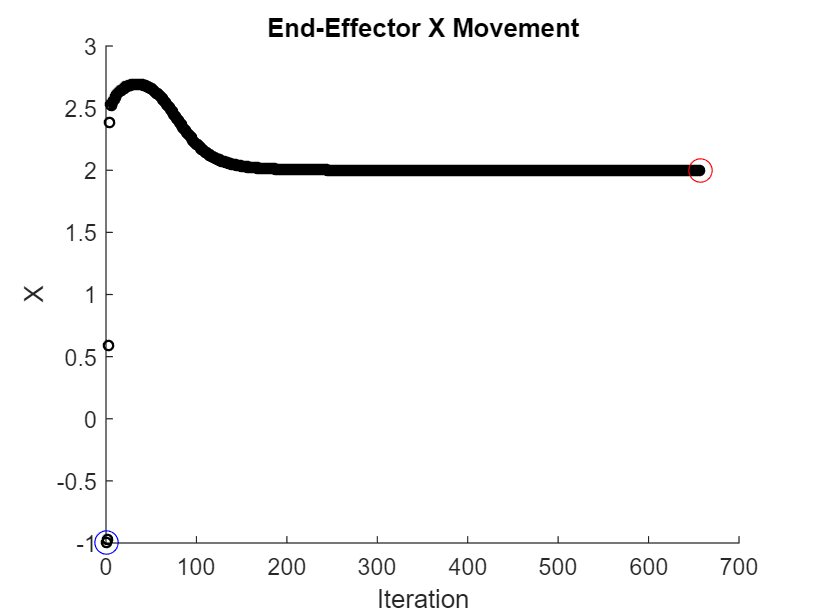



% Display final joint angles
disp('Final Joint Angles:');
disp(['Theta1: ', num2str(theta1)]);
disp(['Theta2: ', num2str(theta2)]);
disp(['Theta3: ', num2str(theta3)]);


% Final end-effector position
figure(fig_x);
plot(iter, x, 'ro', 'MarkerSize', 10, 'DisplayName', 'Final X');
%legend('show');
hold off;

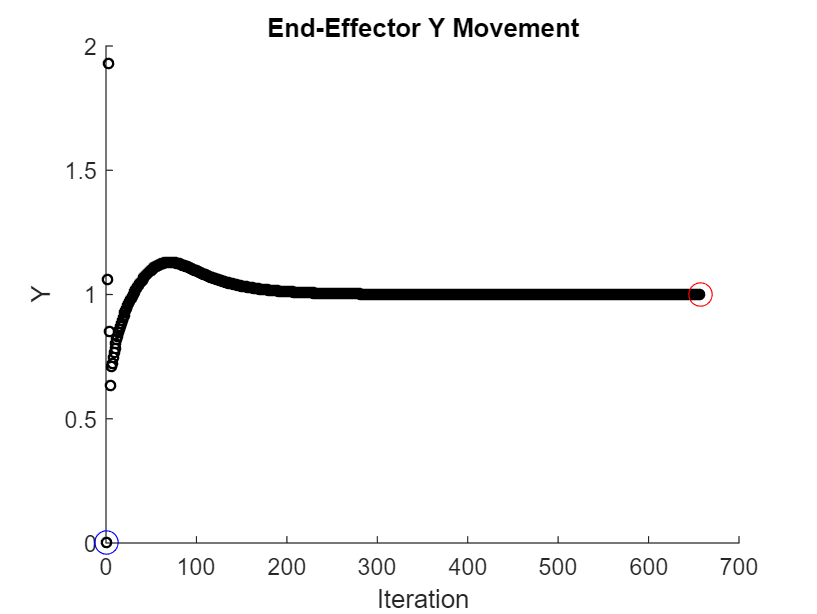


figure(fig_y);
plot(iter, y, 'ro', 'MarkerSize', 10, 'DisplayName', 'Final Y');
%legend('show');
hold off;

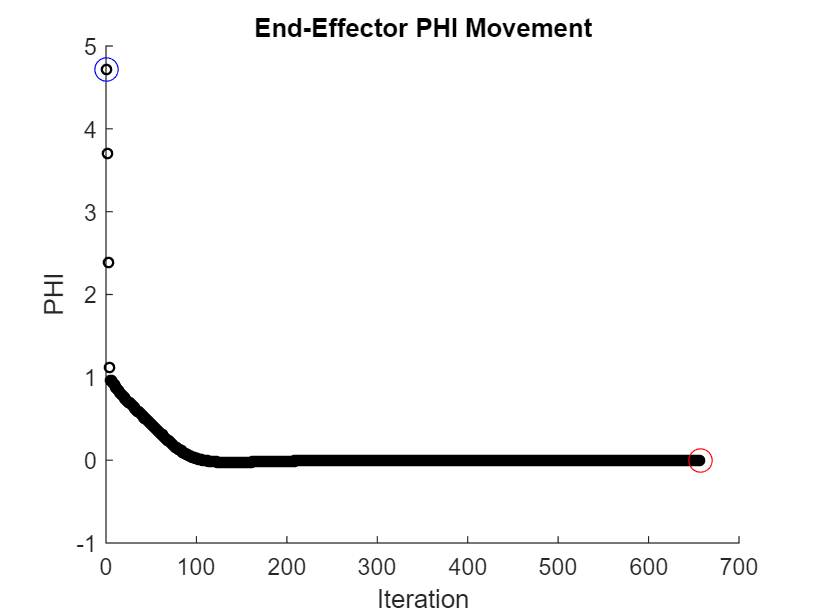


figure(fig_phi);
plot(iter, phi, 'ro', 'MarkerSize', 10, 'DisplayName', 'Final PHI');
%legend('show');
hold off;


% Plot the error
figure;
plot(1:iter, errors(1:iter), 'r-', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Error');
title('Error Convergence');
grid on;